# MIS END SEMISTER PROJCT

## **MATRIX  FACTORIZATION**

**TEAM - 11**

# Least-Squares Optimization Problem

% Model 1 with rating = 1  
% Here we will visualize the rank one model with a single case , where 
% one user's rating one one movie is got by a*b and we take the least 
% squares optimization problem . 

x = -20:20 ;
y = x  ;
[x1,x2] = meshgrid(x,y) ;

Z = (1 - x1.*x2).^2  % function equation

Z =       159201      143641      128881      114921      101761       89401       77841       67081       57121       47961       39601       32041       25281       19321       14161        9801        6241        3481        1521         361           1         441        1681        3721        6561       10201       14641       19881       25921       32761       40401       48841       58081       68121       78961       90601      103041      116281      130321      145161      160801
      143641      129600      116281      103684       91809       80656       70225       60516       51529       43264       35721       28900       22801       17424       12769        8836        5625        3136        1369         324           1         400        1521        3364        5929        9216       13225       17956       23409       29584       36481       44100       52441       61504       71289       81796       93025      104976      117649      131044      145161
      1288

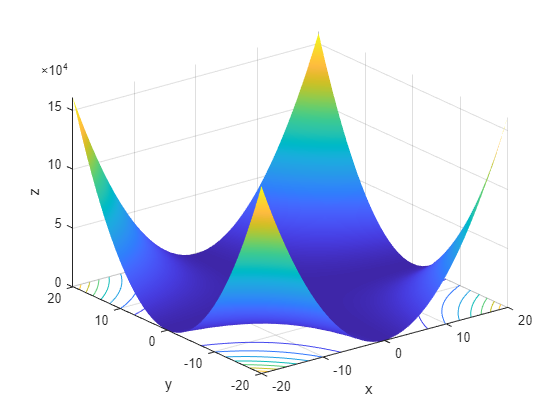

surfc(x1,x2,Z) % ploting it 
shading interp

%Labels
xlabel('x')
ylabel('y')
zlabel('z')

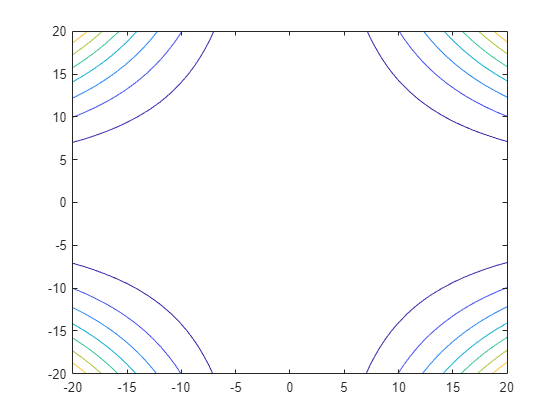


%The contour plot of the function
contour(x1,x2,Z)

# Rank-1 Model 

% Here we extract the a,b features from the matrix using svd .

**Example 1.1 (movies)** MADHAV , SVS , PRASH , LOKI rate the following six movies from 1 to 5.    

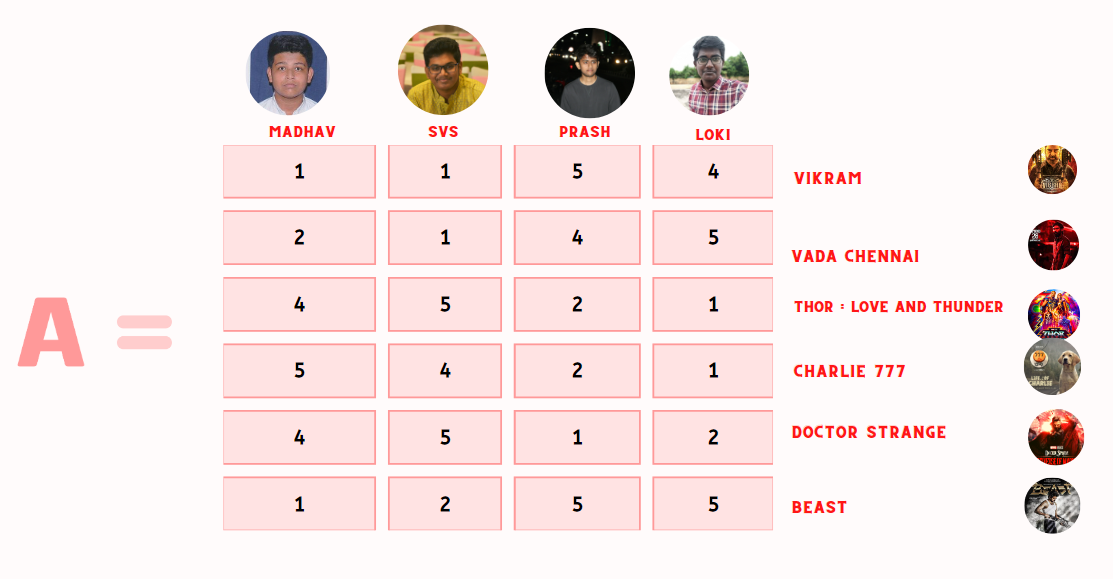

A = [1 1 5 4; 2 1 4 5 ;4 5 2 1 ;5 4 2 1 ;4 5 1 2 ;1 2 5 5] %Rating matrix 

A =      1     1     5     4
     2     1     4     5
     4     5     2     1
     5     4     2     1
     4     5     1     2
     1     2     5     5


s = size(A);
m = s(1);
n = s(2);
mu = (1/(m*n))*sum(sum(A)); %calculating the mean 

ones(s); % creating a matrix of ones of the same size of matrix to centre the data
[U , S ,Vt] = svd(A - mu*ones(s));  % calcualting svd of centred data
S %Note that the 1st singular value is significantly larger . 

S =     7.7851         0         0         0
         0    1.6180         0         0
         0         0    1.5468         0
         0         0         0    0.6180
         0         0         0         0
         0         0         0         0



%The features that we get form out matrix . 
u1 = U(:,1) %a - movies genre

u1 =    -0.4464
   -0.3905
    0.3905
    0.3850
    0.3850
   -0.4464


v1 = Vt(:,1) %b - users taste/likes

v1 =     0.4780
    0.5210
   -0.4780
   -0.5210




App_R1 = mu*ones(s) + S(1,1)*(u1)*(v1') % The features are used to reconstruct the orginal matrix .

App_R1 =     1.3387    1.1893    4.6613    4.8107
    1.5466    1.4160    4.4534    4.5840
    4.4534    4.5840    1.5466    1.4160
    4.4328    4.5616    1.5672    1.4384
    4.4328    4.5616    1.5672    1.4384
    1.3387    1.1893    4.6613    4.8107


norm(App_R1-A) % we see that the matrix regained is almost the same as A

ans = 1.6180

# Rank -R Modle

%  We don't have a right dataset for rank r model 
%  so we generate a random low rank matrix and implement 
%  our rank - r model .  
%  We added a slider so the rank can be set based on the data . 



A = rand(2000,200)*rand(200,2000)*10 ; 

% RANK - r MODEL 
s = size(A);
m = s(1);
n = s(2);
mu = 0 %(1/(m*n))*sum(sum(A)) ;

mu = 0


% RANK 1 MODEL 
ones(s);
[U , S ,Vt] = svd(A - mu*ones(s)); % calcualting svd of centred data
S

S = 	1.0e+06 *

    1.0022         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0025         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   


V=Vt';
n = 1 % setting the n to abstract the features

n = 1


%The features that we get form out matrix . 
u_n = U(:,1:n); %a - movies / might be unintrepretable
v_n = V(1:n,:); %b - user likes / might be unintrepretable
App_Rr =  mu*ones(s) + S(1,1)*(u_n)*(v_n); % reconstructed from features

norm(App_Rr-A) % We see the norm to be small only for rank = 1 , means the random is not perfect 

ans = 2.4508e+03

# **Matrix completion**

% Matrix completing - Localized data example 
% Last row is localized , hence is problamatic for reconstruction

M  = [2 2 2 2;
2 2 2 2;
2 2 2 2;
2 2 2 2;
-3 3 -3 3; ] %localized matrix

M =      2     2     2     2
     2     2     2     2
     2     2     2     2
     2     2     2     2
    -3     3    -3     3



[u,s,vt] = svd(M); % we take svd to analys
v=vt';

u1 = u(:,1) %most entries non zero , so each entry affects all elements of corresponding row

u1 =    -0.5000
   -0.5000
   -0.5000
   -0.5000
   -0.0000


v1 = v(1,:) 

v1 =    -0.5000   -0.5000   -0.5000   -0.5000



u2 = u(:,2) %sparece - so will be localized  

u2 =     0.0000
   -0.0000
    0.0000
    0.0000
   -1.0000


v2 = v(2,:)

v2 =     0.5000   -0.5000    0.5000   -0.5000



S1 = s(1,1)*(u1)*(v1)

S1 =     2.0000    2.0000    2.0000    2.0000
    2.0000    2.0000    2.0000    2.0000
    2.0000    2.0000    2.0000    2.0000
    2.0000    2.0000    2.0000    2.0000
    0.0000    0.0000    0.0000    0.0000


S2 = s(2,2)*(u2)*(v2)

S2 =     0.0000   -0.0000    0.0000   -0.0000
   -0.0000    0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0000   -0.0000
    0.0000   -0.0000    0.0000   -0.0000
   -3.0000    3.0000   -3.0000    3.0000



S1+S2 % RECONSTRUCT THE MATRIX

ans =     2.0000    2.0000    2.0000    2.0000
    2.0000    2.0000    2.0000    2.0000
    2.0000    2.0000    2.0000    2.0000
    2.0000    2.0000    2.0000    2.0000
   -3.0000    3.0000   -3.0000    3.0000


# **CONVEXITY TEST**

***we say ***$f$*** is convex on s if :***


$$f\left(\lambda x+\left(1-\lambda \right)y\;\right)\le \lambda f\left(x\right)+\left(1-\lambda \right)f\left(y\right)$$


   for all x,y $\in$ S and all $\lambda \;\epsilon \;\left\lbrack 0,1\right\rbrack$

### 1) rank()


$$X=\left\lbrack \begin{array}{cc}
5 & 0\\
0 & 0
\end{array}\right\rbrack$$
  
$$Y=\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 5
\end{array}\right\rbrack$$
  
$$\lambda =0\ldotp 1$$



$$\textrm{rank}\left(\left\lbrack \begin{array}{cc}
0\ldotp 5 & 0\\
0 & 4\ldotp 5
\end{array}\right\rbrack \right)$$

$$\not\leq \;$$

$$0\ldotp 1*\mathrm{rank}\left(\left\lbrack \begin{array}{cc}
5 & 0\\
0 & 0
\end{array}\right\rbrack \right)+0\ldotp 9*\mathrm{rank}\left(\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 5
\end{array}\right\rbrack \right)$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;2\;\;\;\;\;\;\;\;\;\;\;\;\;\not\leq 0\ldotp 1*1\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\;\;\;\;\;\;\;\;\;\;0\ldotp 9*1$$
            

x = [5 0;0 0]

x =      5     0
     0     0


y = [0 0;0 5]

y =      0     0
     0     5


la = 0.1

la = 0.1000

aaa=rank(la*x + (1-la)*y)

aaa = 2

bbb=0.1*rank(x) + 0.9*rank(y)

bbb = 1

### **2) Nuclear Norm**

$\textrm{Let}\;x:=\left\lbrack \begin{array}{c}
5\\
0
\end{array}\right\rbrack \;\textrm{and}\;y:=\left\lbrack \begin{array}{c}
0\\
5
\end{array}\right\rbrack$       for any $\lambda \;\epsilon \;\left(0,1\right)$


$${||\lambda x+\;\left(1-\lambda \right)y||}_* \le {\lambda ||x||}_* +\left(1-\lambda \;\right){||y||}_*$$



$$\lambda =0\ldotp 1$$



$$\left\lbrack \begin{array}{c}
0\ldotp 707\\
0
\end{array}\right\rbrack \le \left\lbrack \begin{array}{c}
5\\
0
\end{array}\right\rbrack$$


x= [5 0]';
y = [0 5]';
la = 0.1;
c= la*x+la*y;
x11=norm(svd(c,"vector"));

x22 = la*norm(svd(x)) + (1-la)*norm(svd(y))

x22 = 5

# **Using CVX to solve the constrained Opt Problem**

%Solving using CVX 

syms x1  x2 x3 x4 
X = [1 x1 5 4 ; x2 1 4 5 ; 4 5 2 x3 ; 5 4 2 1 ; 4 5 1 2 ; 1 2 x4 5] %matrix with unknown as variables

$$X = \left(\begin{array}{cccc} 1 & x_{1} & 5 & 4\\ x_{2} & 1 & 4 & 5\\ 4 & 5 & 2 & x_{3}\\ 5 & 4 & 2 & 1\\ 4 & 5 & 1 & 2\\ 1 & 2 & x_{4} & 5 \end{array}\right)$$


f = sum(sum(X)) %summing for caculating average 

$$f = x_{1}+x_{2}+x_{3}+x_{4}+63$$

mu = vpa(subs(f,[x1 x2 x3 x4],[0 0 0 0])/20) % mean is calculated

$$mu = 3.15$$

mu = double(mu)

mu = 3.1500

m = 6;
n = 4;
lambda = 1;
 

% CVX baseline
cvx_begin quiet
  variable X(m,n)
  minimize(norm_nuc(X))    % minimizing nuclear norm 
   
  subject to               % constrains: the given values are the known part of matrix
      X(1,1)==1-mu
      X(1,3)==5-mu
      X(1,4)==4-mu
      X(2,2)==1-mu
      X(2,3)==4-mu
      X(2,4)==5-mu
      X(3,1)==4-mu
      X(3,2)==5-mu
      X(3,3)==2-mu
      X(4,:)==[5,4,2,1]-mu
      X(5,:)==[4,5,1,2]-mu
      X(6,1)==1-mu
      X(6,2)==2-mu
      X(6,4)==5-mu
  cvx_end
round(full(X)+mu)      % Final matrix is rounded , it almost match the orginal matches 

ans =      1     3     5     4
     2     1     4     5
     4     5     2     2
     5     4     2     1
     4     5     1     2
     1     2     5     5


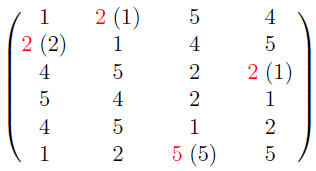

# **Using cvx to solve the unconstrained Opt Problem.**

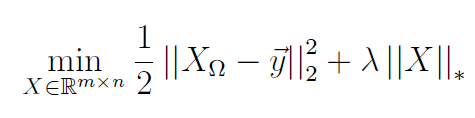


%Solving using CVX 

lamda = 0.15 % hyper parameter set after trying many 

lamda = 0.1500


%CVX
cvx_begin quiet
  variable X(6,4) 
   y = [1 ; 5 ;4 ; 1 ;4 ;5 ;4 ;5 ;2 ;5; 4; 2; 1 ;4 ;5 ;1 ;2 ;1 ;2; 5] -mu ;  % the known part of matrix 
  subject to                                                         % constrains
  xx =[X(1,1);X(1,3);X(1,4);X(2,2);X(2,3);X(2,4);X(3,1);
X(3,2);X(3,3);X(4,1);X(4,2);X(4,3);X(4,4);X(5,1);X(5,2);
X(5,3);X(5,4);X(6,1);X(6,2);X(6,4);]

 
xx =
 
    cvx real affine expression (20x1 vector)
 


    minimize( 0.5*norm(xx - y,2) + lamda*norm_nuc(X)) ;     % cost function
cvx_end

  round(X+mu) % Final matrix is rounded , it almost match the orginal matches 

ans =      1     3     5     4
     2     1     4     5
     4     5     2     2
     5     4     2     1
     4     5     1     2
     1     2     5     5


  

# Solving Proximal Based on Algorithm

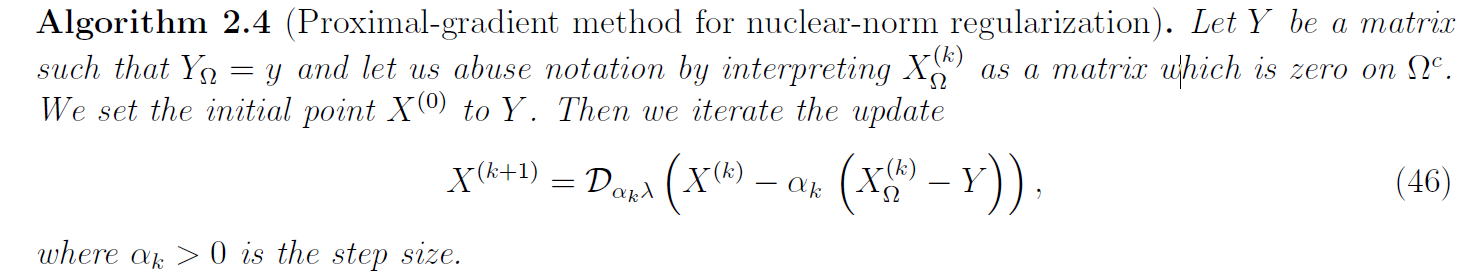

%  to find an optimal value for the
%  hyperparameters alpha and threshold values so we have exprimented with
%  several combnations of different range  .
 

A = [1 1 5 4; 2 1 4 5 ;4 5 2 1 ;5 4 2 1 ;4 5 1 2 ;1 2 5 5] %matrix 

A =      1     1     5     4
     2     1     4     5
     4     5     2     1
     5     4     2     1
     4     5     1     2
     1     2     5     5


Y = [1 0 5 4 ; 0 1 4 5 ; 4 5 2 0 ; 5 4 2 1 ; 4 5 1 2 ; 1 2 0 5] - mu %the matrix missing elements zero

Y =    -2.1500   -3.1500    1.8500    0.8500
   -3.1500   -2.1500    0.8500    1.8500
    0.8500    1.8500   -1.1500   -3.1500
    1.8500    0.8500   -1.1500   -2.1500
    0.8500    1.8500   -2.1500   -1.1500
   -2.1500   -1.1500   -3.1500    1.8500



Y(1,2)=0;
Y(2,1)=0;
Y(3,4)=0;
Y(6,3)=0;
X = Y

X =    -2.1500         0    1.8500    0.8500
         0   -2.1500    0.8500    1.8500
    0.8500    1.8500   -1.1500         0
    1.8500    0.8500   -1.1500   -2.1500
    0.8500    1.8500   -2.1500   -1.1500
   -2.1500   -1.1500         0    1.8500



[n1,n2] = size(Y);
small = 99999999  ;% setting small value to compare results

%different combinations of hyper parametres tested 
for q=[-9:9] 
    for p=[-9:9] 


        alpha = 10^(p);
        threshold = 10^(q) ;
        
        %We do a 100 itrations , as larger ones yielded bad results
        for i =[0:100] 
            XK = X;
            
            XK(1,2)=0;
            XK(2,1)=0;
            XK(3,4)=0;
            XK(6,3)=0;
            X = Sft_thresh_singular_vals( X - alpha*( XK - Y),threshold); % update as per algorithm
        
        end
         
        if small > norm(X+mu - A) 
            small = norm(X+mu - A);
            s=X;
            val = [10^(p),10^(q)];  % optimal hyperparameter

        end    
    end
end    
    
 % optimal hyperparameter
val(1) % optimal alpha

ans = 1

val(2) % optimal threshold

ans = 1.0000e-09

round(s+mu)

ans =      1     2     5     4
     2     1     4     5
     4     5     2     2
     5     4     2     1
     4     5     1     2
     1     2     4     5


function D = Sft_thresh_singular_vals(Y,tou)
    %Soft thresholding of singular values based the given parameter tou
    [U,S,Vt]  = svd(Y);
    [m,n] = size(S);
    for i = [1:n-1]
    if S(i,i) > tou 
        S(i,i) = S(i,i) - tou;   % we subract if > tou
    else
        S(i,i) = 0;              % else it will be set to 0
    end
    end   
    D = U*S*Vt;                  %Final matrix that we return 
    
end